## Modelling and Control of Flexible Systems

## BAMOSS Marked Seminar

**- Akash Sharma**

**- Deeksha Kota**

clear
clc
close all
format short e

## Required Parameters

% Lames:
l=0.286;     % m
h=0.04;      % m
e=0.00064;    % m
E=200e9;      % N/m2

J=0.015;    % Kgm
L=0.335;     % m
m=0.30;      % Kg

%Calcul raideur quivalente:
I=h*e^3/12;
k=3*E*I/l^3;
we=sqrt(k/m);  % pulsation encastre de la lame:

% Inertie totale:
Jt=J+2*m*L^2;

% Matrice de masse:
M=[Jt m*L -m*L;m*L m 0; -m*L 0 m];
% Matrice de raideur: 
K=[0 0 0;0 k 0;0 0 k];
% Matrice d'amortissement: 
D=[0 0 0;0 0.001 0;0 0 0.001];
% Matrice d'entree
F=[1;0;0];


## State-Space Representation

% State-Space matrices are defined based on the Lagrange equation

A = [  zeros(3)  eye(3)
     -inv(M)*K -inv(M)*D];

B = [zeros(3,1)
     inv(M)*F];

C = [1 0 0 0 0 0
     0 0 0 1 0 0
     0 0 0 1 3/(2*l) 0];

D = zeros(3,1);

sys = ss(A,B,C,D)

sys =
 
  A = 
             x1        x2        x3        x4        x5        x6
   x1         0         0         0         1         0         0
   x2         0         0         0         0         1         0
   x3         0         0         0         0         0         1
   x4         0     500.5    -500.5         0   0.02233  -0.02233
   x5         0    -242.4     167.7         0  -0.01082  0.007482
   x6         0     167.7    -242.4         0  0.007482  -0.01082
 
  B = 
           u1
   x1       0
   x2       0
   x3       0
   x4   66.67
   x5  -22.33
   x6   22.33
 
  C = 
          x1     x2     x3     x4     x5     x6
   y1      1      0      0      0      0      0
   y2      0      0      0      1      0      0
   y3      0      0      0      1  5.245      0
 
  D = 
       u1
   y1   0
   y2   0
   y3   0
 
Continuous-time state-space model.



## Question A.5

damp(A)

                                                                        
         Pole              Damping       Frequency       Time Constant  
                                       (rad/TimeUnit)     (TimeUnit)    
                                                                        
  0.00e+00                -1.00e+00       0.00e+00               Inf    
  0.00e+00                -1.00e+00       0.00e+00               Inf    
 -9.15e-03 + 2.02e+01i     4.52e-04       2.02e+01          1.09e+02    
 -9.15e-03 - 2.02e+01i     4.52e-04       2.02e+01          1.09e+02    
 -1.67e-03 + 8.64e+00i     1.93e-04       8.64e+00          6.00e+02    
 -1.67e-03 - 8.64e+00i     1.93e-04       8.64e+00          6.00e+02    


These eigen values are frequencies of different modes of the free undamped system. They match the ones obtained through the calculations by hand. Complex poles come in symmetric pairs according to the equation $s=j\omega$. Therefore, for 3 values of $\omega^2$, we get 6 complex conjugate poles. These poles are shown in the first column. After drawing the modal shapes, we find that the frequencies of each mode.

#### $\omega_1 =0$ --> Rigid modes

#### $\omega_2 =\sqrt{\left(\frac{k}{m}\right)}=8\ldotp 64$ --> Symmetric Flexible Modes

#### $\omega_3 =\sqrt{\left(\frac{k}{m}\frac{J_t }{J}\right)}=20\ldotp 2$ --> Anti-Symmetric Flexible Modes

## Controllability and Observability Analysis

The 2 MATLAB functions **ctrbf** and **obsvf** are used to determine controllability and observability of each of the modes. 

The **ctrbf** function converts the matrices into a staircase form where the **number** of controllable and uncontrollable modes can be identified through the $\bar{A}$ and $\bar{B}$ matrices. Once this is known, by indexing the $\bar{A}$ matrix, we can find exactly which modes are controllable and uncontrollable. The sub-matrices $A_c$ and $A_{\textrm{uc}}$ that carry information about the controllability of the modes, are sliced from the $\bar{A}$ matrix according to this configuration.


$$\bar{A} =\left\lbrack \begin{array}{cc}
A_{\textrm{uc}}  & 0\\
A_{21}  & A_c 
\end{array}\right\rbrack$$
   
$$\bar{B} =\left\lbrack \begin{array}{c}
0\\
B_c 
\end{array}\right\rbrack$$


### Controllability Analysis

states = 6;
[Abar_con,Bbar_con,Cbar_con,~,k_con] = ctrbf(A,B,C);
Abar_con

Abar_con =    2.1714e+01  -8.0777e+00  -3.1992e-14   1.0668e-15   8.1561e-15   4.0876e-17
   6.7627e+01  -2.1717e+01  -5.7605e-14   1.2025e-15   1.4548e-16   1.6334e-16
  -3.4398e-13   1.1296e-13   2.6777e-03   1.0000e+00   9.3093e-15   4.1774e-18
  -1.1632e-13  -2.7590e-13  -6.1011e+01  -4.2679e-02   2.8905e+01   9.4713e-17
   6.2571e-15  -2.4396e-15  -7.8688e-02  -5.5102e-05   3.7279e-02   1.0000e+00
   1.7551e-12   3.2355e-12   7.3675e+02   5.1592e-01  -3.4905e+02  -1.5574e-02


sum(k_con) % Number of controllable modes

ans =      4


uncon_states = states - sum(k_con);

Auc = Abar_con(1:uncon_states,1:uncon_states);
Ac = Abar_con(uncon_states+1:states,uncon_states+1:states);

damp(Ac)

                                                                        
         Pole              Damping       Frequency       Time Constant  
                                       (rad/TimeUnit)     (TimeUnit)    
                                                                        
 -9.15e-03 + 2.02e+01i     4.52e-04       2.02e+01          1.09e+02    
 -9.15e-03 - 2.02e+01i     4.52e-04       2.02e+01          1.09e+02    
  8.54e-08                -1.00e+00       8.54e-08         -1.17e+07    
 -8.54e-08                 1.00e+00       8.54e-08          1.17e+07    


**Controllable modes - rigid modes & anti-symmetric modes**

damp(Auc)

                                                                        
         Pole              Damping       Frequency       Time Constant  
                                       (rad/TimeUnit)     (TimeUnit)    
                                                                        
 -1.67e-03 + 8.64e+00i     1.93e-04       8.64e+00          6.00e+02    
 -1.67e-03 - 8.64e+00i     1.93e-04       8.64e+00          6.00e+02    


**Uncontrollable modes - symmetric modes**

### **Obervability Analysis**

The strategy used to obtain insight on observability using th **obsvf** function is the same as that of controllability, the only difference being that observability has to be checked with respect to **one specific output at a time**. Hence, the system is indexed for each output one by one. The configuration followed in this case is as follows.


$$\bar{A} =\left\lbrack \begin{array}{cc}
A_{\textrm{no}}  & A_{12} \\
0 & A_o 
\end{array}\right\rbrack$$
   
$$\bar{B} =\left\lbrack \begin{array}{c}
B_{\textrm{no}} \\
B_o 
\end{array}\right\rbrack$$


#### **Observability with respect with **$\theta$

sys1 = sys(1,:);

[Abar_obs1,Bbar_obs1,Cbar_obs1,~,k_obs1] = obsvf(sys1.A,sys1.B,sys1.C);
Abar_obs1

Abar_obs1 =    5.6425e-04  -1.0000e+00   6.8390e-17   6.3021e-16            0            0
   7.4705e+01  -3.8976e-03   1.1469e-16   8.8744e-16            0            0
  -4.0119e-14  -1.3076e-18  -4.4620e-05  -4.1006e+02            0            0
  -3.2716e-18  -1.0091e-16   1.0000e+00  -1.8252e-02            0            0
   5.6843e-14  -1.7347e-18  -9.5067e-18   7.0785e+02            0            0
            0            0            0            0   1.0000e+00            0


sum(k_obs1) % Number of observable modes

ans =      4


unob_states = states - sum(k_obs1);

Ano = Abar_obs1(1:unob_states,1:unob_states);   
Ao = Abar_obs1(unob_states+1:states,unob_states+1:states);


damp(Ao)

                                                                        
         Pole              Damping       Frequency       Time Constant  
                                       (rad/TimeUnit)     (TimeUnit)    
                                                                        
  0.00e+00                -1.00e+00       0.00e+00               Inf    
  0.00e+00                -1.00e+00       0.00e+00               Inf    
 -9.15e-03 + 2.02e+01i     4.52e-04       2.02e+01          1.09e+02    
 -9.15e-03 - 2.02e+01i     4.52e-04       2.02e+01          1.09e+02    


**Observable modes - rigid modes & anti-symmetric modes**

damp(Ano)

                                                                        
         Pole              Damping       Frequency       Time Constant  
                                       (rad/TimeUnit)     (TimeUnit)    
                                                                        
 -1.67e-03 + 8.64e+00i     1.93e-04       8.64e+00          6.00e+02    
 -1.67e-03 - 8.64e+00i     1.93e-04       8.64e+00          6.00e+02    


**Unobservable modes - symmetric modes**

#### **Observability with respect with **$\dot{\theta}$

sys2 = sys(2,:);

[Abar_obs2,Bbar_obs2,Cbar_obs2,~,k_obs2] = obsvf(sys2.A,sys2.B,sys2.C);
Abar_obs2

Abar_obs2 =   -2.3165e+01            0  -6.6515e+01   7.3589e-14  -1.9908e-13            0
            0            0            0            0            0  -1.0000e+00
   9.1898e+00            0   2.3162e+01  -2.5596e-14  -4.5444e-13            0
  -9.3428e-14            0  -3.1937e-14  -4.4620e-05  -4.1006e+02            0
   1.2850e-16            0   1.2953e-16   1.0000e+00  -1.8252e-02            0
   1.4211e-13            0            0  -1.6137e-13   7.0785e+02            0


sum(k_obs2) % Number of observable modes

ans =      3


unob_states = states - sum(k_obs2);

Ano = Abar_obs2(1:unob_states,1:unob_states);
Ao = Abar_obs2(unob_states+1:states,unob_states+1:states);

damp(Ao)

                                                                        
         Pole              Damping       Frequency       Time Constant  
                                       (rad/TimeUnit)     (TimeUnit)    
                                                                        
  0.00e+00                -1.00e+00       0.00e+00               Inf    
 -9.15e-03 + 2.02e+01i     4.52e-04       2.02e+01          1.09e+02    
 -9.15e-03 - 2.02e+01i     4.52e-04       2.02e+01          1.09e+02    


**Observable modes - 1 rigid mode & anti-symmetric modes**

damp(Ano)

                                                                        
         Pole              Damping       Frequency       Time Constant  
                                       (rad/TimeUnit)     (TimeUnit)    
                                                                        
 -1.67e-03 + 8.64e+00i     1.93e-04       8.64e+00          6.00e+02    
 -1.67e-03 - 8.64e+00i     1.93e-04       8.64e+00          6.00e+02    
  0.00e+00                -1.00e+00       0.00e+00               Inf    


**Unobservable modes - 1 rigid mode & symmetric modes**

#### **Observability with respect with **$\dot{\beta}$

sys3 = sys(3,:);

[Abar_obs3,Bbar_obs3,Cbar_obs3,~,k_obs3] = obsvf(sys3.A,sys3.B,sys3.C);
Abar_obs3

Abar_obs3 =   -6.9389e-16  -9.1795e-01   3.3518e-03  -3.4969e-01  -7.3670e-06  -1.8729e-01
   2.5395e-14  -2.9548e-03   1.6613e+02   1.6018e+00  -5.7440e+02   1.9396e-02
   1.7395e-16   3.9672e-01  -2.0852e+00  -8.2931e-01   4.7631e+00  -4.3351e-01
   3.3107e-14   1.6564e-15   2.1688e+02   2.0832e+00  -4.9427e+02   1.1072e-02
  -2.1901e-18  -3.9007e-17   1.7257e-17   4.7214e-01  -1.0403e-02  -8.8153e-01
  -3.1597e-17  -6.8216e-15   1.3159e-14   1.4714e-14   1.6085e+02  -6.3268e-03


sum(k_obs3) % Number of observable modes

ans =      5


unob_states = states - sum(k_obs3);

Ano = Abar_obs3(1:unob_states,1:unob_states);
Ao = Abar_obs3(unob_states+1:states,unob_states+1:states);


damp(Ao)

                                                                        
         Pole              Damping       Frequency       Time Constant  
                                       (rad/TimeUnit)     (TimeUnit)    
                                                                        
 -9.15e-03 + 2.02e+01i     4.52e-04       2.02e+01          1.09e+02    
 -9.15e-03 - 2.02e+01i     4.52e-04       2.02e+01          1.09e+02    
  1.65e-15                -1.00e+00       1.65e-15         -6.05e+14    
 -1.67e-03 + 8.64e+00i     1.93e-04       8.64e+00          6.00e+02    
 -1.67e-03 - 8.64e+00i     1.93e-04       8.64e+00          6.00e+02    


**Observable modes - 1 rigid mode, symmetric modes & anti-symmetric modes**

damp(Ano)

                                                            
   Pole        Damping       Frequency       Time Constant  
                           (rad/TimeUnit)     (TimeUnit)    
                                                            
 -6.94e-16     1.00e+00       6.94e-16          1.44e+15    


**Unobservable modes - 1 rigid mode**

## Poles & Zeros of Transfer Functions

#### Transfer between u & $\theta$

poles = pole(sys1)

poles =    0.0000e+00 + 0.0000e+00i
   0.0000e+00 + 0.0000e+00i
  -9.1483e-03 + 2.0250e+01i
  -9.1483e-03 - 2.0250e+01i
  -1.6667e-03 + 8.6432e+00i
  -1.6667e-03 - 8.6432e+00i


- **2 poles at **$\omega_1$

- **2 poles at **$\omega_2$

- **2 poles at **$\omega_3$

zeros = tzero(sys1)

zeros =   -1.6667e-03 + 8.6432e+00i
  -1.6667e-03 - 8.6432e+00i
  -1.6667e-03 + 8.6432e+00i
  -1.6667e-03 - 8.6432e+00i


- **4 zeros at **$\omega_2$

zpk(sys1) % Transfer function between u and theta

ans =
 
           66.667 (s^2 + 0.003333s + 74.71)^2
  -----------------------------------------------------
  s^2 (s^2 + 0.003333s + 74.71) (s^2 + 0.0183s + 410.1)
 
Continuous-time zero/pole/gain model.



sys1_min = minreal(zpk(zeros,poles,66.67)) % Minimum realization of this system

sys1_min =
 
  66.67 (s^2 + 0.003333s + 74.71)
  -------------------------------
    s^2 (s^2 + 0.0183s + 410.1)
 
Continuous-time zero/pole/gain model.



**The poles at symmetric modes are cancelled by the zeros.**

### Transfer between u and $\dot{\theta}$

poles = pole(sys2)

poles =    0.0000e+00 + 0.0000e+00i
  -9.1483e-03 + 2.0250e+01i
  -9.1483e-03 - 2.0250e+01i
  -1.6667e-03 + 8.6432e+00i
  -1.6667e-03 - 8.6432e+00i
   0.0000e+00 + 0.0000e+00i


- **2 poles at **$\omega_1$

- **2 poles at **$\omega_2$

- **2 poles at **$\omega_3$

zeros = tzero(sys2)

zeros =   -1.6667e-03 + 8.6432e+00i
  -1.6667e-03 - 8.6432e+00i
  -1.6667e-03 + 8.6432e+00i
  -1.6667e-03 - 8.6432e+00i
   0.0000e+00 + 0.0000e+00i


- **4 zeros at **$\omega_2$

- **1 zero at **$\omega_1$

zpk(sys2) % Transfer function between u and theta_dot

ans =
 
          66.667 (s^2 + 0.003333s + 74.71)^2
  ---------------------------------------------------
  s (s^2 + 0.003333s + 74.71) (s^2 + 0.0183s + 410.1)
 
Continuous-time zero/pole/gain model.



sys2_min = minreal(zpk(zeros,poles,1)) % Minimum realization of this system

sys2_min =
 
  (s^2 + 0.003333s + 74.71)
  -------------------------
  s (s^2 + 0.0183s + 410.1)
 
Continuous-time zero/pole/gain model.



**1 rigid mode and the symmetric modes are cancelled by the zeros.**

### Transfer between u and $\dot{\beta}$

poles = pole(sys3)

poles =    0.0000e+00 + 0.0000e+00i
  -9.1483e-03 + 2.0250e+01i
  -9.1483e-03 - 2.0250e+01i
  -1.6667e-03 + 8.6432e+00i
  -1.6667e-03 - 8.6432e+00i
   0.0000e+00 + 0.0000e+00i


- **2 poles at **$\omega_1$

- **2 poles at **$\omega_2$

- **2 poles at **$\omega_3$

zeros = tzero(sys3)

zeros =   -9.9319e+00 + 0.0000e+00i
   9.9363e+00 + 0.0000e+00i
  -1.6667e-03 + 8.6432e+00i
  -1.6667e-03 - 8.6432e+00i
   0.0000e+00 + 0.0000e+00i


- **2 zeros at **$\omega_2$

- **1 zero at **$\omega_1$

- **1 zero at **$\omega_4 =-9\ldotp 932$

- **1 non-minimum zero at **$\omega_5 =9\ldotp 936$

zpk(sys3) % Transfer function between u and beta_dot

ans =
 
  -50.466 (s+9.932) (s-9.936) (s^2 + 0.003333s + 74.71)
  -----------------------------------------------------
   s (s^2 + 0.003333s + 74.71) (s^2 + 0.0183s + 410.1)
 
Continuous-time zero/pole/gain model.



sys3_min = minreal(zpk(zeros,poles,1)) % Minimum realization of this system

sys3_min =
 
     (s+9.932) (s-9.936)
  -------------------------
  s (s^2 + 0.0183s + 410.1)
 
Continuous-time zero/pole/gain model.



**1 rigid mode and the symmetric modes are cancelled by the zeros.**

## Question A.6

In order to interpret the bode plots of the 3 transfers, the behaviour is analyzed at all the relevant frequencies of each system in increasing order. The effect of amplification or attenuation along with resonance is highlighted along with changes in the gain magnitude slope and the phase.

### Transfer between u and $\theta$

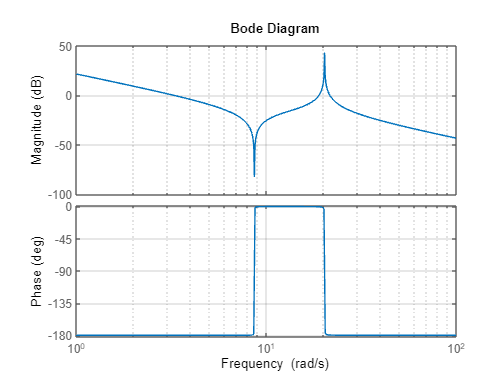

bode(sys1)
grid on

$\omega =0$ (2 poles)

    These poles attenuate the input signal

    Magnitude plot slope = -40db/decade

    Phase difference = -180$\degree$

$\omega =8\ldotp 64$ (2 zeros)

    These zeros cause anti-resonance at this frequency

    Magnitude plot slope = 0db/decade

    Phase difference = 0$\degree$

$\omega =20\ldotp 2$ (2 poles)

    These zeros cause resonance at this frequency

    Magnitude plot slope = -40db/decade

    Phase difference = -180$\degree$

### Transfer between u and $\dot{\theta}$

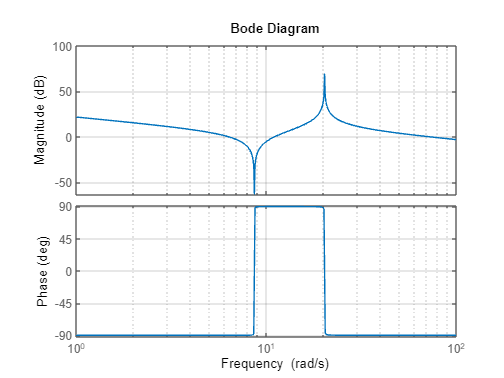

bode(sys2)
grid on

$\omega =0$ (1 pole)

    This pole attenuates the input signal

    Magnitude plot slope = -20db/decade

    Phase difference = -90$\degree$

$\omega =8\ldotp 64$ (2 zeros)

    These zeros cause anti-resonance at this frequency

    Magnitude plot slope = 20db/decade

    Phase difference = 90$\degree$

$\omega =20\ldotp 2$ (2 poles)

    These zeros cause resonance at this frequency

    Magnitude plot slope = -20db/decade

    Phase difference = -90$\degree$

### Transfer between u and $\dot{\beta}$

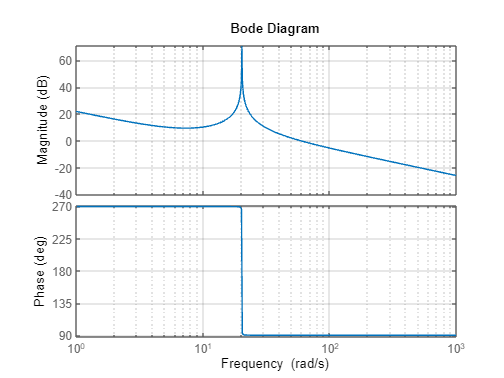

bode(sys3)
grid on

- We know that $\beta \approx \theta$. Therefore, it's bode plot is similar to that of $\theta$. The bode plot of $\dot{\beta}$ can be explained by looking at $\beta$. $\dot{\beta}$ is just $\beta$ with an added zero at s=0. Therefore, the phase increases from -180$\degree$ to -90$\degree$ which is the same as 270$\degree$.

- This bode plot shows that non-minimum zeros do not produce any anti-resonance.

- We only observe resonance due to the anti-symmetric modes.

One important thing to note is that all the resonances and anti-resonances are quite high which is due to poor damping of the system.

## Question A.7

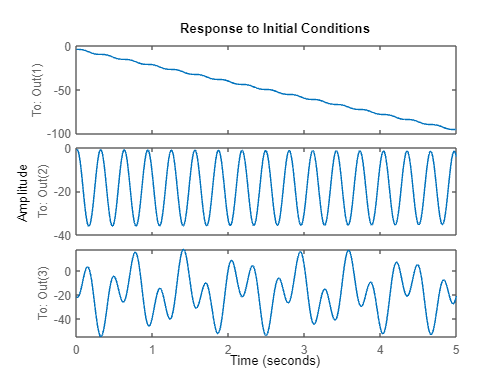

x0 = [deg2rad(-4),2e-3,0.0e-3,deg2rad(-1),-7e-2,18e-2];  % Initial Conditions
Tfinal = 5;  % Final time to plot
initial((180/pi)*eye(3)*sys,x0,Tfinal)

### Output $\theta$

The rigid and anti-symmetric modes are observable in the $\theta$ graph. The rigid modes correspond to just rotation of the structure about its axis which is seen as a continuously increasing $\theta$. The slight vibration of $\theta$ is because of the anti-symmetric vibrations. We can also approximate the slope of this line as follows.

$\dot{\theta} \approx -\frac{100}{\textrm{Tfinal}}=-\frac{100}{5}=-20$            We see that theta reaches about 100 rad/s in 5 seconds. Therefore, $\dot{\theta =-20}$

### Output $\dot{\theta}$

Only 1 rigid mode and the anti-symmetric modes are observable in the $\dot{\theta}$ graph. The frequency of the oscillations seen in this graph is equal to $\omega_3$ and $\dot{\theta}$ oscillates about the value of -20 which is due to the contribution of the observed rigid mode.

### Output $\dot{\beta}$

In the $\dot{\beta}$ graph, all modes except 1 rigid mode are observable. The 1 observable rigid mode causes the output to oscillate about -20 again while the symmetric and anti-symmetric modes merge by the superimposition of 2 sine waves of frequencies $\omega_2$ and $\omega_3$ respectively. For the first few seconds, the non-minimum phase is also observed.

## Question B.1

The objective is to tune the gains by assuming a rigid body model and verifying whether the resulting control law is able to control the flexible system as well.

The gain expressions were calculated by hand and are as follows.


$$\begin{array}{l}
K_p =J_t \omega^2 \\
K_d =2J_t \xi \omega 
\end{array}$$


omega = 2;
epsilon = 0.707;

Kp = omega^2*Jt;
Kd = 2*epsilon*omega*Jt;

These gains are feedback gains on $\theta$ and $\dot{\theta}$ respectively while $\dot{\beta}$ has not feedback. Therefore, the gain vector becomes -


$$K=\left\lbrack \begin{array}{ccc}
K_p  & K_d  & 0
\end{array}\right\rbrack$$


CL_sys = feedback(sys,[Kp Kd 0])*Kp

CL_sys =
 
  A = 
             x1        x2        x3        x4        x5        x6
   x1         0         0         0         1         0         0
   x2         0         0         0         0         1         0
   x3         0         0         0         0         0         1
   x4    -21.96     500.5    -500.5    -15.52   0.02233  -0.02233
   x5     7.355    -242.4     167.7       5.2  -0.01082  0.007482
   x6    -7.355     167.7    -242.4      -5.2  0.007482  -0.01082
 
  B = 
           u1
   x1       0
   x2       0
   x3       0
   x4   21.96
   x5  -7.355
   x6   7.355
 
  C = 
          x1     x2     x3     x4     x5     x6
   y1      1      0      0      0      0      0
   y2      0      0      0      1      0      0
   y3      0      0      0      1  5.245      0
 
  D = 
       u1
   y1   0
   y2   0
   y3   0
 
Continuous-time state-space model.



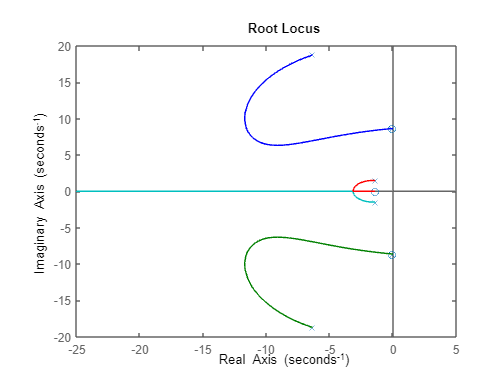

OL_sys = [Kp Kd 0]*CL_sys; % Open-loop system with PD controller
rlocus(OL_sys)%; hold on; rlocus(OL_sys,1,'r+')

We have the following observations from this graph -

- The poles of the anti-symmetric modes are placed further in the stable half of the plane.

- The rigid mode poles are controlled in a similar way.

- The poles of the symmetric modes do not change location. This confirms the previous results that **symmetric modes are uncontrollable.**

- Since the final system is stable, this proves that the tuned gains for a rigid model can be used for a flexible model as well.

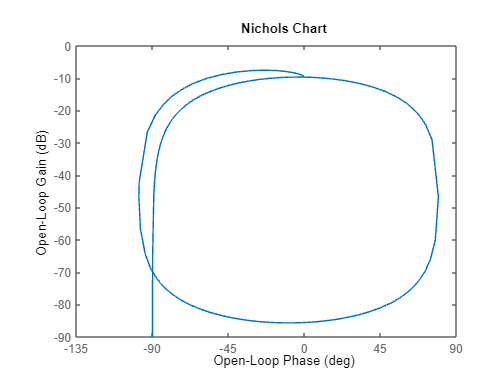

nichols(OL_sys)

## Question B.2

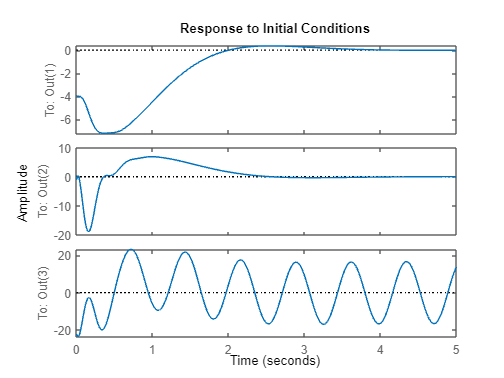

initial((180/pi)*eye(3)*CL_sys,x0,Tfinal)

- The first 2 graphs show a controlled response since all the observed modes in these graphs are controllable. (rigid and anti-symmetric modes)

- The 3rd graph, however, is able to observe the symmetric mode which is uncontrollable. Therefore, we see continuous oscillations about the null-point.

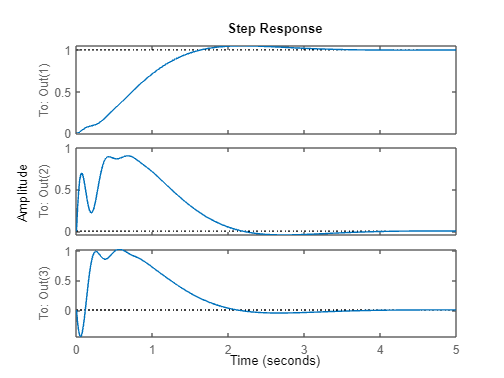

step(CL_sys)

The excitation in the step does not excite sufficiently the symmetric mode to cause sustained oscillations.

## Question B.3

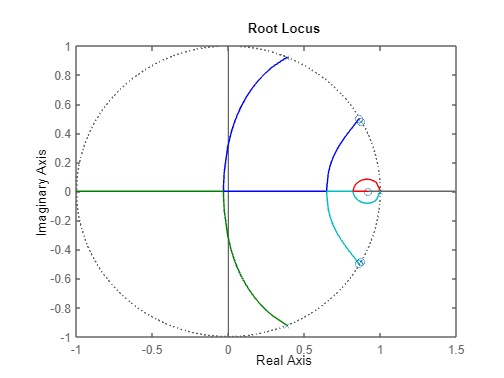

Ts = 0.058; % Sampling Time
sys_d = c2d(sys,Ts); % Discrete system
rlocus([Kp Kd 0]*sys_d)

In a discrete system, the region of a unit circle is the region of stability which corresponds to the left-half plane in continuous systems. The P-D control law is still able to stabilize the discrete system since all poles are within this region.

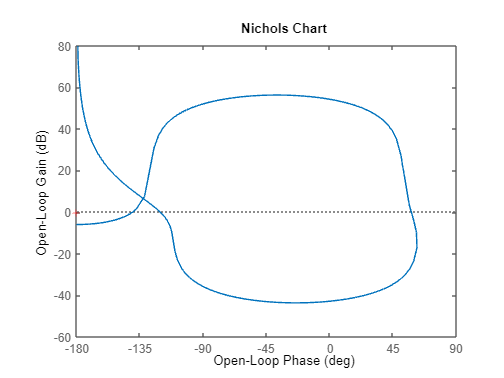

nichols([Kp Kd 0]*sys_d)

It was found that a sampling period $T_s =0\ldotp 058$s corresponds to a gain margin.

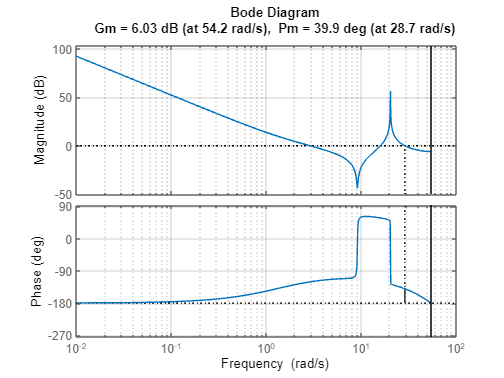

margin([Kp Kd 0]*sys_d)
grid on

## Question B.4

Since the feedback is now on $\theta$ and $\dot{\beta}$, the K vector now becomes -


$$K=\left\lbrack \begin{array}{ccc}
K_p  & 0 & K_d 
\end{array}\right\rbrack$$



$$\dot{\beta} =\dot{\theta} +\dot{\alpha}$$


Since the system is assumed to be rigid, we can write,


$$\dot{\beta} \approx \dot{\theta}$$


Therefore, the same Kp and Kd tuned values can be used here as well.

CL_sys = feedback(sys,[Kp 0 Kd])

CL_sys =
 
  A = 
             x1        x2        x3        x4        x5        x6
   x1         0         0         0         1         0         0
   x2         0         0         0         0         1         0
   x3         0         0         0         0         0         1
   x4    -21.96     500.5    -500.5    -15.52    -81.39  -0.02233
   x5     7.355    -242.4     167.7       5.2     27.26  0.007482
   x6    -7.355     167.7    -242.4      -5.2    -27.27  -0.01082
 
  B = 
           u1
   x1       0
   x2       0
   x3       0
   x4   66.67
   x5  -22.33
   x6   22.33
 
  C = 
          x1     x2     x3     x4     x5     x6
   y1      1      0      0      0      0      0
   y2      0      0      0      1      0      0
   y3      0      0      0      1  5.245      0
 
  D = 
       u1
   y1   0
   y2   0
   y3   0
 
Continuous-time state-space model.



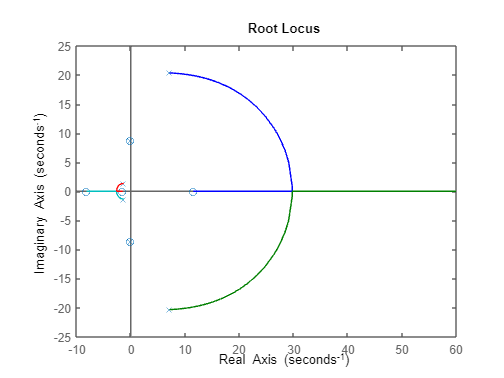

OL_sys = [Kp 0 Kd]*CL_sys; % Open-loop system with PD controller
rlocus(OL_sys)

By measuring $\dot{\beta}$, the location of our actuator and sensor is no longer the same. **This means the system is not colocated**. Such systems are difficult to control as can be seen in this root locus plot where the poles become unstable.

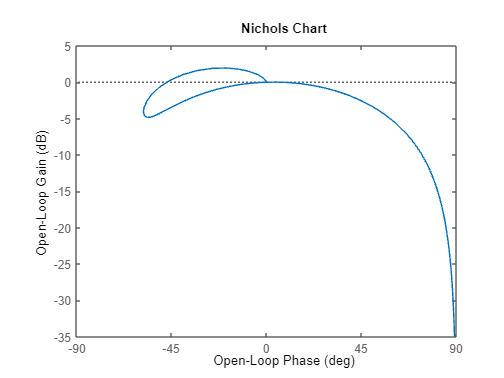

nichols(OL_sys)

### Filter Design

To design the filter, the rltool was used to stabilize the open loop system.

s = tf('s');
filter = -1.7692*(s-1.957)/(s+7.711)

filter =
 
  -1.769 s + 3.462
  ----------------
     s + 7.711
 
Continuous-time transfer function.



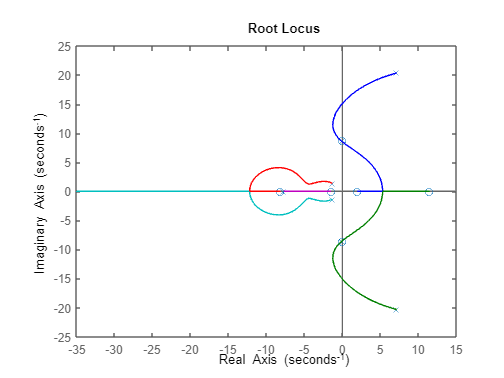

CL_sys = feedback(sys,[Kp 0 Kd]);
OL_sys = filter*OL_sys;
rlocus(OL_sys)

As we can see, this filter has moved part of the root locus to the stable half plane which means for a few select gains, the system can be stable.

## Conclusion

Modal Analysis is a useful and efficient way to find poles(open-loop modal analysis) and zeros(closed-loop modal analysis). The resulting poles are all the flexible modes of the system that is defined.

While designing flexible systems, the notion of colocation is vital to design a controller for it. The actuators and sensors have to be positioned together to obtain better controllability, observability and stability.